## 4.2.3

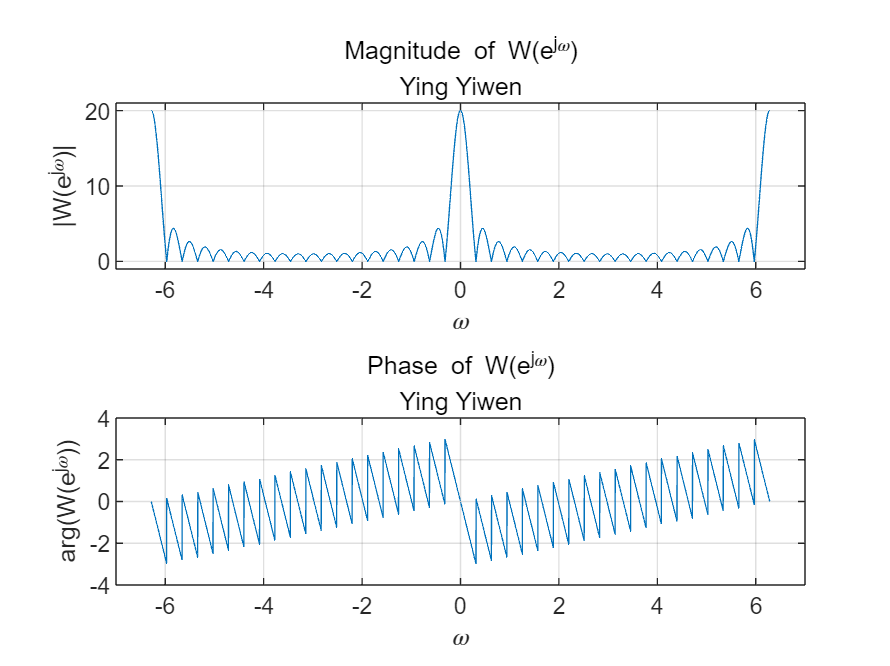

clc,clear,close all;
w = -2*pi:pi/1000:2*pi;
N = 20;
W = (mod(w,2*pi)==0).*N + (mod(w,2*pi)~=0).*exp(-1j*w*(N-1)/2).*sin(w*N/2)./(sin(w/2));
figure;
subplot(2,1,1),plot(w,abs(W)),xlabel('\omega'),ylabel('|W(e^{j\omega})|'),title('Magnitude of W(e^{j\omega})','Ying Yiwen'),axis([-7 7 -1 21]),grid on;
subplot(2,1,2),plot(w,angle(W)),xlabel('\omega'),ylabel('arg(W(e^{j\omega}))'),title('Phase of W(e^{j\omega})','Ying Yiwen'),axis([-7 7 -4 4]),grid on;

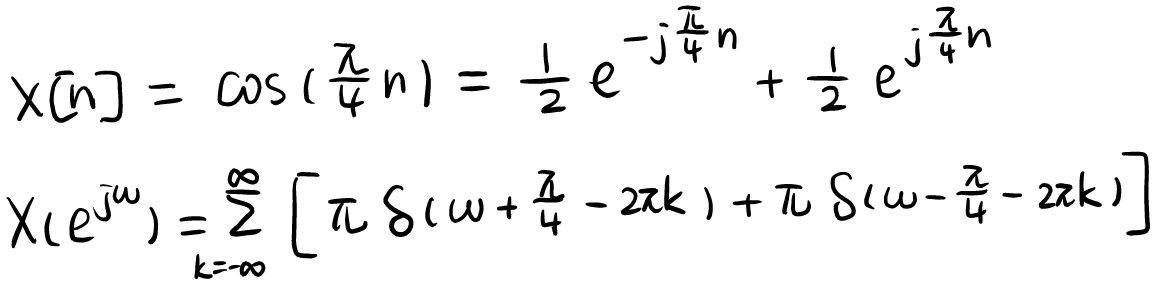

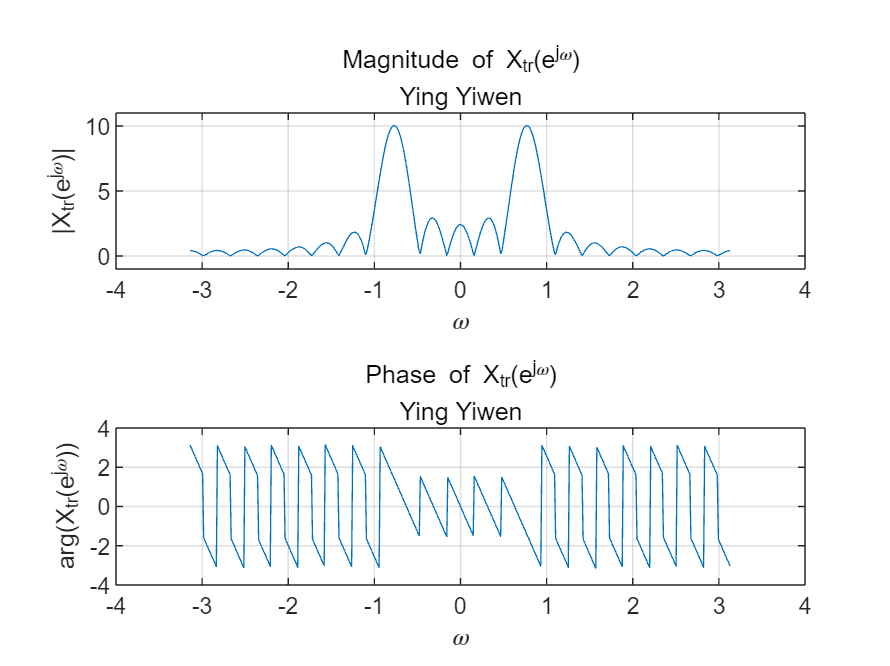

n = -10:10;
x = cos(pi*n/4);
[X, w] = DTFT(x,512);
figure;
subplot(2,1,1),plot(w,abs(X)),xlabel('\omega'),ylabel('|X_{tr}(e^{j\omega})|'),title('Magnitude of X_{tr}(e^{j\omega})','Ying Yiwen'),axis([-4 4 -1 11]),grid on;
subplot(2,1,2),plot(w,angle(X)),xlabel('\omega'),ylabel('arg(X_{tr}(e^{j\omega}))'),title('Phase of X_{tr}(e^{j\omega})','Ying Yiwen'),axis([-4 4 -4 4]),grid on;

Describe the difference.

X_tr(e^{jw}) only takes a part of x into consideration, in this case, specificly, is a window of length 20. While X(e^{jw}) consider the whole x[n] into consideration. So the wave of X_tr(e^{jw}) isn't so ideal to be like X(e^{jw}). It has small oscillating other from -pi/4 and pi/4. 

Comment on the effects of using a different length of the window.

If the length of window become larger, X_tr(e^{jw}) is more similar with X(e^{jw}).

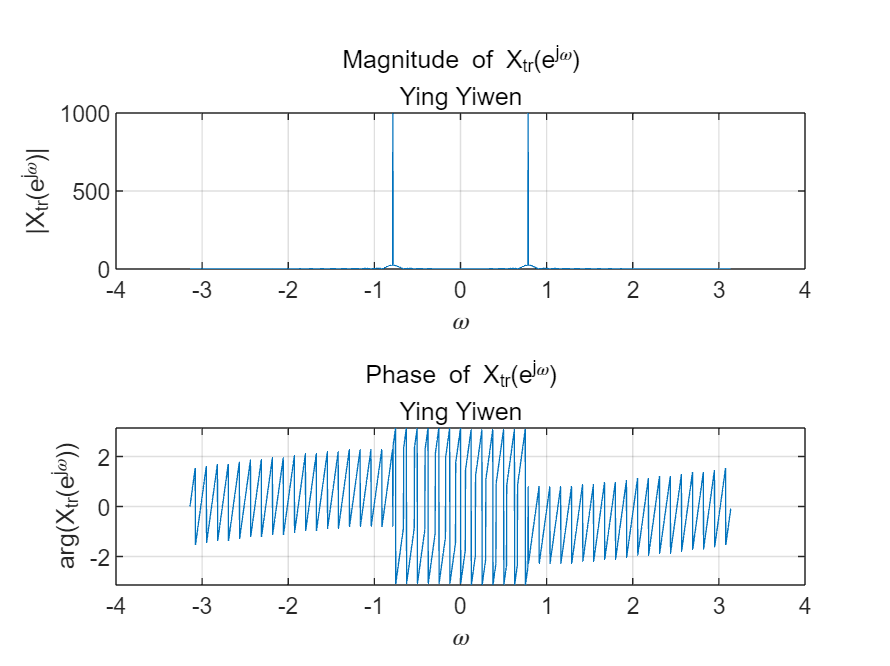

n = -999:999;
x = cos(pi*n/4);
[X, w] = DTFT(x,512);
figure;
subplot(2,1,1),plot(w,abs(X)),xlabel('\omega'),ylabel('|X_{tr}(e^{j\omega})|'),title('Magnitude of X_{tr}(e^{j\omega})','Ying Yiwen'),grid on;
subplot(2,1,2),plot(w,angle(X)),xlabel('\omega'),ylabel('arg(X_{tr}(e^{j\omega}))'),title('Phase of X_{tr}(e^{j\omega})','Ying Yiwen'),grid on;

## 4.3.1

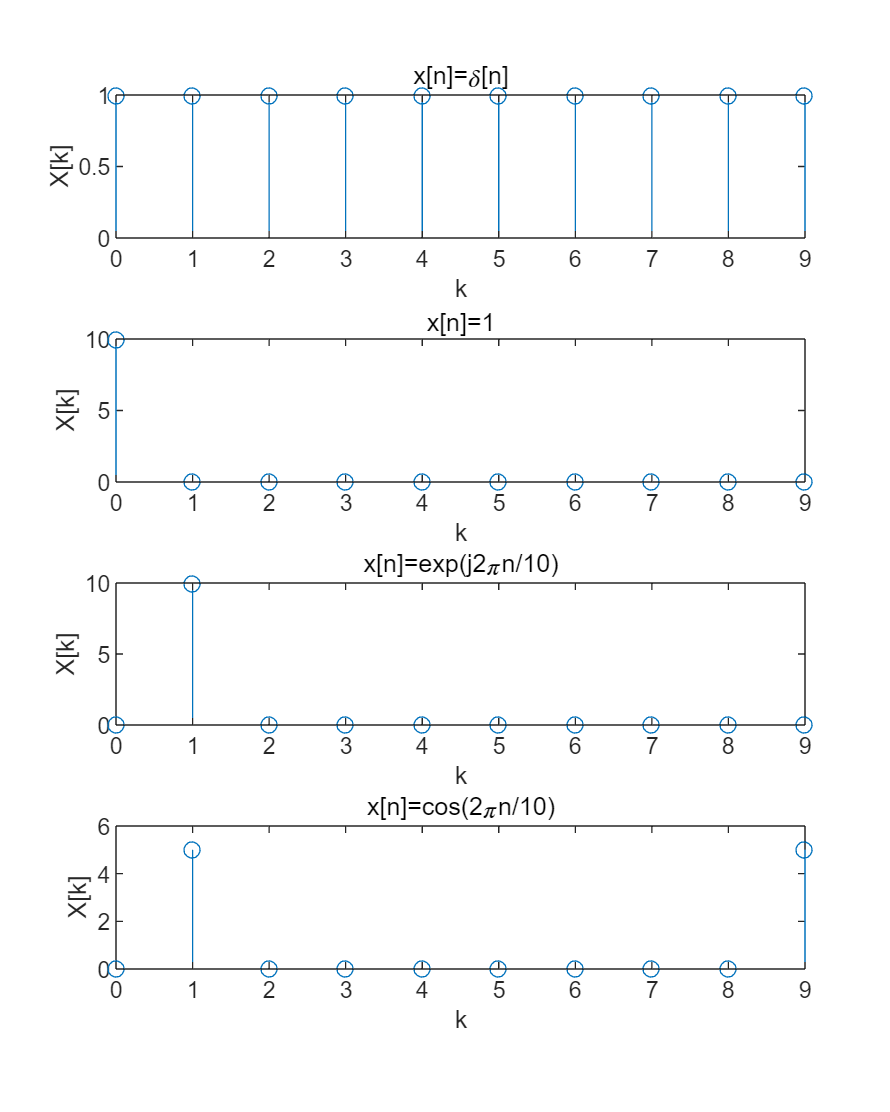

clc,clear,close all;
n = 0:9;
x1 = (n==0);
X1 = DFTsum(x1);
x2 = ones(1,10);
X2 = DFTsum(x2);
x3 = exp(1j*2*pi*n/10);
X3 = DFTsum(x3);
x4 = cos(2*pi*n/10);
X4 = DFTsum(x4);
figure('Position',[100,100,800,1000]);
subplot(4,1,1),stem(0:9,abs(X1)),xlabel('k'),ylabel('X[k]'),title('x[n]=\delta[n]');
subplot(4,1,2),stem(0:9,abs(X2)),xlabel('k'),ylabel('X[k]'),title('x[n]=1');
subplot(4,1,3),stem(0:9,abs(X3)),xlabel('k'),ylabel('X[k]'),title('x[n]=exp(j2\pin/10)');
subplot(4,1,4),stem(0:9,abs(X4)),xlabel('k'),ylabel('X[k]'),title('x[n]=cos(2\pin/10)');

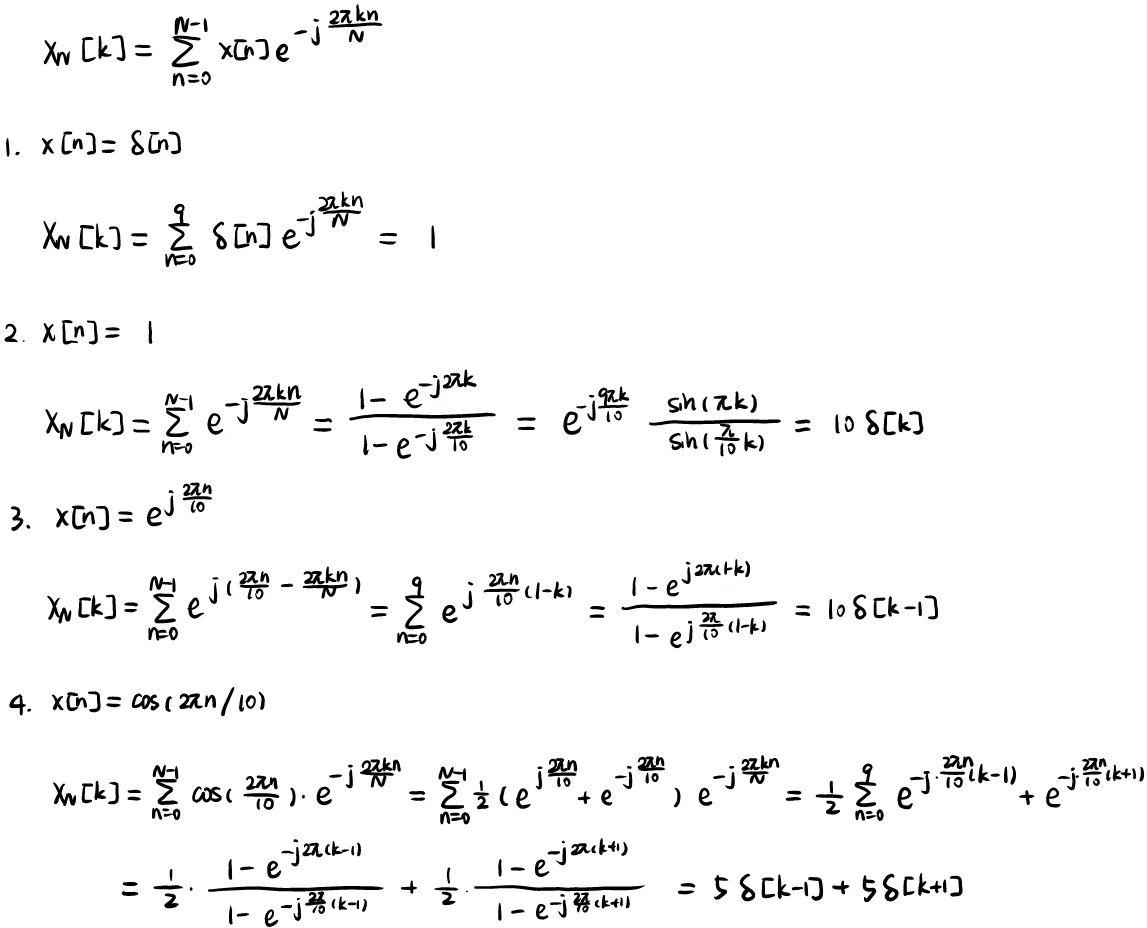

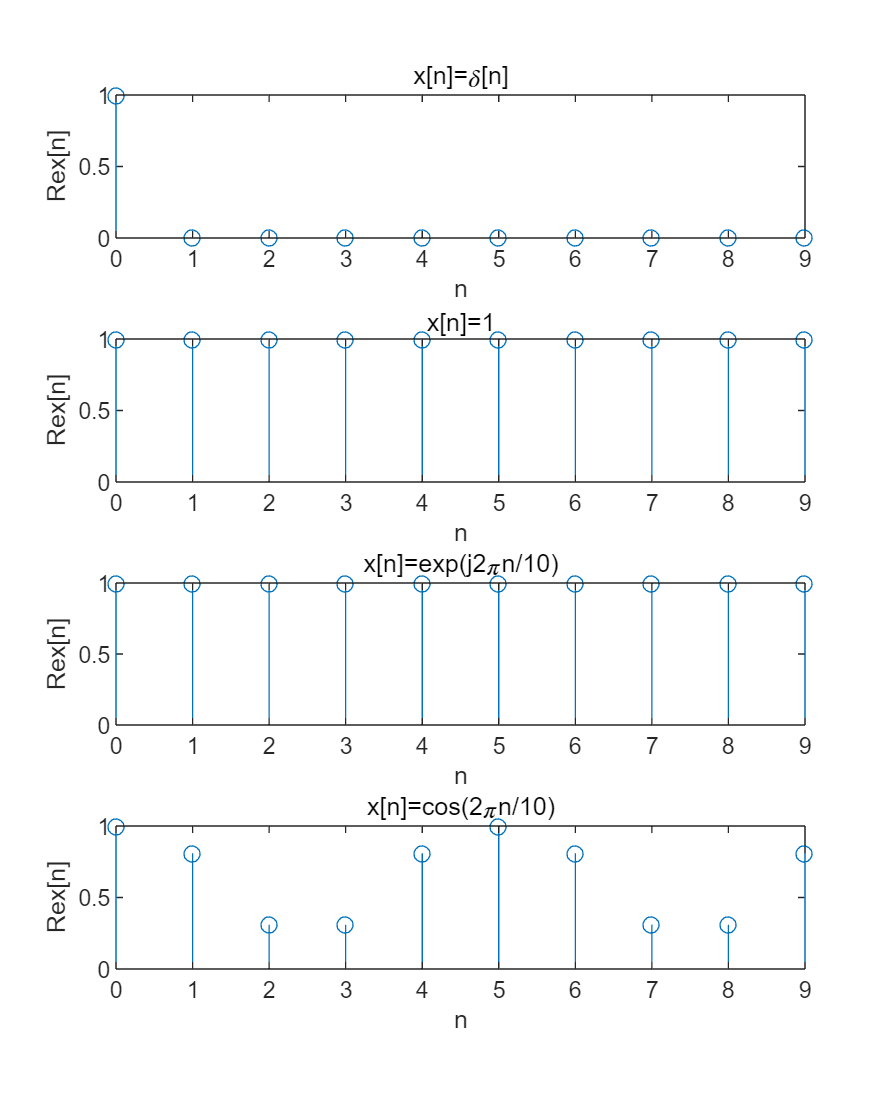

y1 = IDFTsum(X1);
y2 = IDFTsum(X2);
y3 = IDFTsum(X3);
y4 = IDFTsum(X4);
figure('Position',[100,100,800,1000]);
subplot(4,1,1),stem(0:9,abs(y1)),xlabel('n'),ylabel('Re{x[n]}'),title('x[n]=\delta[n]');
subplot(4,1,2),stem(0:9,abs(y2)),xlabel('n'),ylabel('Re{x[n]}'),title('x[n]=1');
subplot(4,1,3),stem(0:9,abs(y3)),xlabel('n'),ylabel('Re{x[n]}'),title('x[n]=exp(j2\pin/10)');
subplot(4,1,4),stem(0:9,abs(y4)),xlabel('n'),ylabel('Re{x[n]}'),title('x[n]=cos(2\pin/10)');

## 4.3.2

A = DFTmatrix(5)

A =    1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i
   1.0000 + 0.0000i   0.3090 - 0.9511i  -0.8090 - 0.5878i  -0.8090 + 0.5878i   0.3090 + 0.9511i
   1.0000 + 0.0000i  -0.8090 - 0.5878i   0.3090 + 0.9511i   0.3090 - 0.9511i  -0.8090 + 0.5878i
   1.0000 + 0.0000i  -0.8090 + 0.5878i   0.3090 - 0.9511i   0.3090 + 0.9511i  -0.8090 - 0.5878i
   1.0000 + 0.0000i   0.3090 + 0.9511i  -0.8090 + 0.5878i  -0.8090 - 0.5878i   0.3090 - 0.9511i


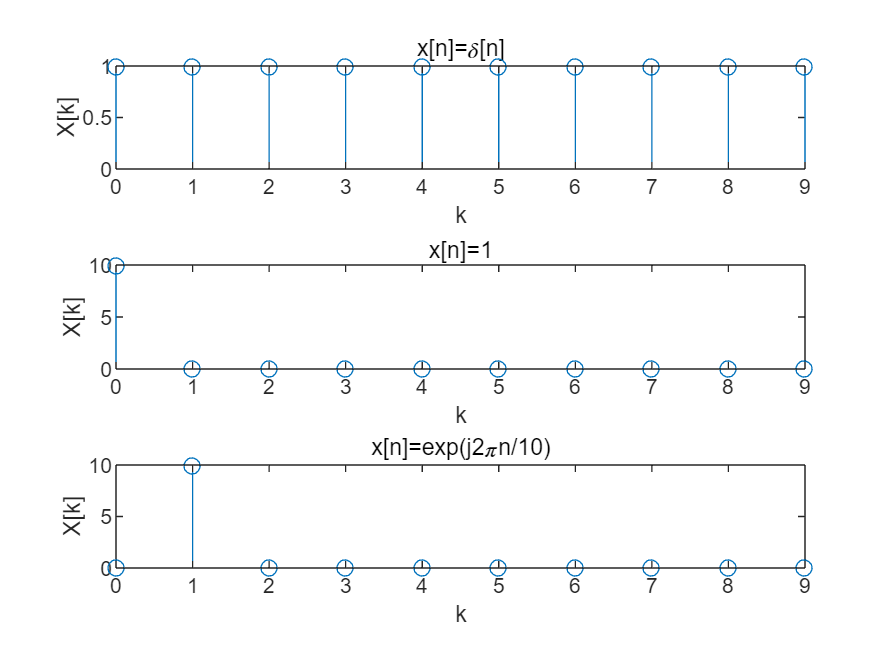

A = DFTmatrix(10);
Z1 = A*x1.';
Z2 = A*x2.';
Z3 = A*x3.';
figure;
subplot(3,1,1),stem(0:9,abs(Z1)),xlabel('k'),ylabel('X[k]'),title('x[n]=\delta[n]');
subplot(3,1,2),stem(0:9,abs(Z2)),xlabel('k'),ylabel('X[k]'),title('x[n]=1');
subplot(3,1,3),stem(0:9,abs(Z3)),xlabel('k'),ylabel('X[k]'),title('x[n]=exp(j2\pin/10)');

How many multiplies are required to compute an 𝑁 point DFT using the matrix method?

N^2 multiplies in DFTmatrix

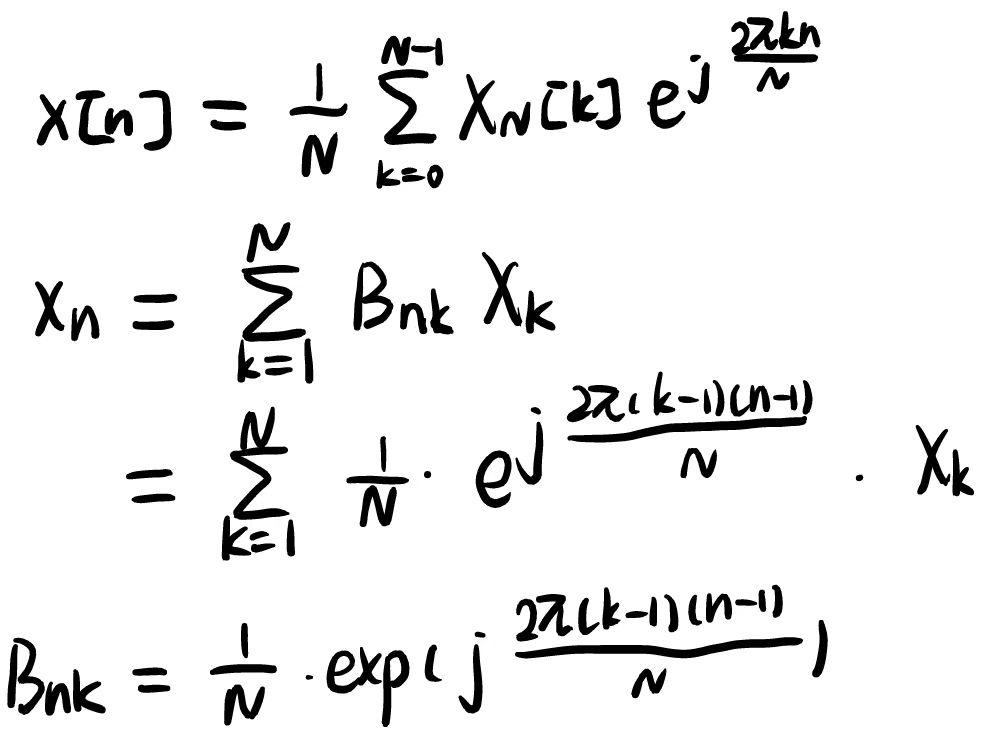

B = IDFTmatrix(5)

B =    0.2000 + 0.0000i   0.2000 + 0.0000i   0.2000 + 0.0000i   0.2000 + 0.0000i   0.2000 + 0.0000i
   0.2000 + 0.0000i   0.0618 + 0.1902i  -0.1618 + 0.1176i  -0.1618 - 0.1176i   0.0618 - 0.1902i
   0.2000 + 0.0000i  -0.1618 + 0.1176i   0.0618 - 0.1902i   0.0618 + 0.1902i  -0.1618 - 0.1176i
   0.2000 + 0.0000i  -0.1618 - 0.1176i   0.0618 + 0.1902i   0.0618 - 0.1902i  -0.1618 + 0.1176i
   0.2000 + 0.0000i   0.0618 - 0.1902i  -0.1618 - 0.1176i  -0.1618 + 0.1176i   0.0618 + 0.1902i


A = DFTmatrix(5);
C = B * A

C =    1.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i
  -0.0000 + 0.0000i   1.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i
   0.0000 + 0.0000i  -0.0000 + 0.0000i   1.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   1.0000 + 0.0000i  -0.0000 - 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   1.0000 + 0.0000i


What form does 𝐂 have? Why does it have this form?

C is identity matrix. Because A is the matrix for DFT, B is the matrix for IDFT, Cx=BAx=BX=x, so C is I

## 4.3.3

clc,clear,close all;
n = 0:511;
x = cos(2*pi*n/10);
A = DFTmatrix(512);
disp('matrix method:');

matrix method:


t = cputime;
X = A * x.';
cputime - t

ans = 0

disp('sum method:');

sum method:


t = cputime;
X = DFTsum(x);
cputime - t

ans = 0.0469

Which method is faster? Which method requires less storage?

matrix method is faster, sum method use less storage

function X = DFTsum(x)
    N = length(x);
    X = zeros(1, N);
    for k = 0:N-1
        for n = 0:N-1
            X(k+1) = X(k+1) + x(n+1) * exp(-1j * 2 * pi * k * n / N);
        end
    end
end

function x = IDFTsum(X)
    N = length(X);
    x = zeros(1,N);
    for k = 0:N-1
        for n = 0:N-1
            x(k+1) = x(k+1) + X(n+1) * exp(1j * 2 * pi * k * n / N);
        end
        x(k+1) = x(k+1) / N;
    end
end

function A = DFTmatrix(N)
    A = zeros(N,N);
    for k = 1:N
        for n = 1:N
            A(k,n) = exp(-1j * 2 * pi * (k-1) * (n-1) / N);
        end
    end
end

function B = IDFTmatrix(N)
    B = zeros(N,N);
    for k = 1:N
        for n = 1:N
            B(n,k) = exp(1j * 2 * pi * (k-1) * (n-1) / N) / N;
        end
    end
end